clearvars
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')

cast03 = readSBScnv( 'at30_003_hyst.cnv' ); % Default hysteresis
cast04 = readSBScnv( 'at30_004_hyst.cnv' );
cast05 = readSBScnv( 'at30_005_hyst.cnv' );
cast06 = readSBScnv( 'at30_006_hyst.cnv' );
cast09 = readSBScnv( 'at30_009_hyst.cnv' );
cast10 = readSBScnv( 'at30_010_hyst.cnv' );
cast11 = readSBScnv( 'at30_011_hyst.cnv' );
cast12 = readSBScnv( 'at30_012_hyst.cnv' );
cast13 = readSBScnv( 'at30_013_hyst.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')

btl = readtable('Irminger_Sea-02_AT30-01_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum03 = btl(btl.Cast == 3,:);
btlsum04 = btl(btl.Cast == 4,:);
btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year2')
btl03 = readtable('at30_003_hyst.csv','TextType','string');

btl04 = readtable('at30_004_hyst.csv','TextType','string');

btl05 = readtable('at30_005_hyst.csv','TextType','string');

btl06 = readtable('at30_006_hyst.csv','TextType','string');

btl09 = readtable('at30_009_hyst.csv','TextType','string');

btl10 = readtable('at30_010_hyst.csv','TextType','string');

btl11 = readtable('at30_011_hyst.csv','TextType','string');

btl12 = readtable('at30_012_hyst.csv','TextType','string');

btl13 = readtable('at30_013_hyst.csv','TextType','string');


% Join tables 
btlsum03 = join(btl03,btlsum03,'Keys',"Bottle");
btlsum04 = join(btl04,btlsum04,'Keys',"Bottle");
btlsum05 = join(btl05,btlsum05,'Keys',"Bottle");
btlsum06 = join(btl06,btlsum06,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12,btlsum12,'Keys',"Bottle");
btlsum13 = join(btl13,btlsum13,'Keys',"Bottle");

clear btl0* btl1* btl2*


% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 
cal.SOC = double(5.15150e-001);
cal.VOFFSET = double(-5.24000e-001);
cal.A = double(-4.56860e-003);
cal.B = double(2.57580e-004);
cal.C = double(-4.06010e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.11000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0712';
cal.OCALDATE = '05-Nov-14';

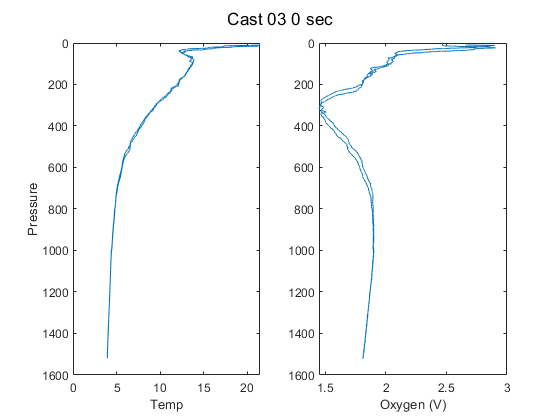

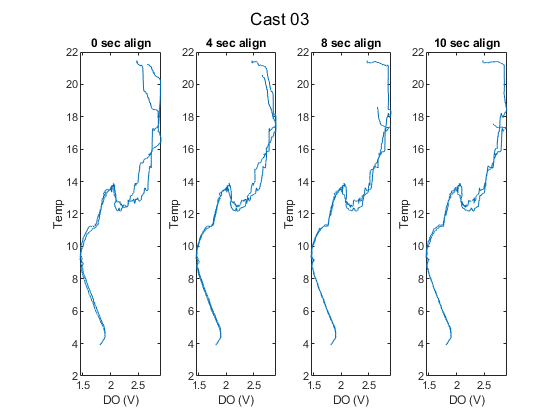

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 8; a3 = 10;

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

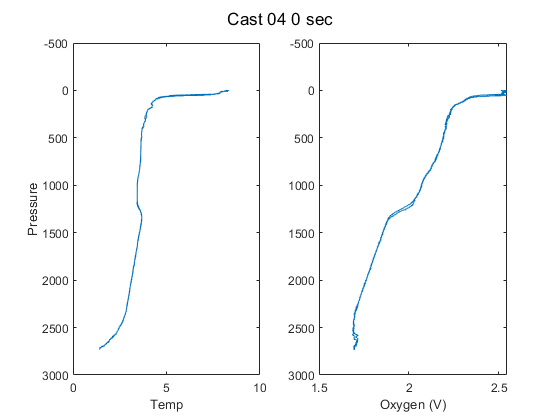

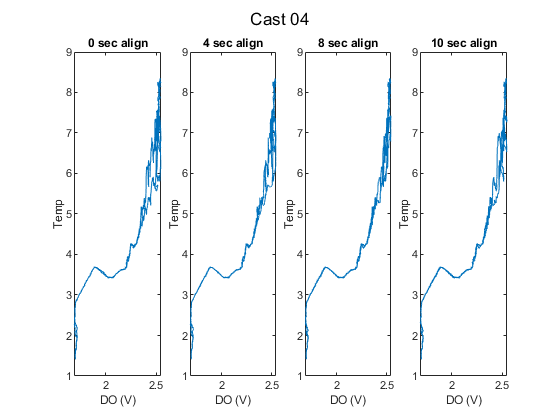

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

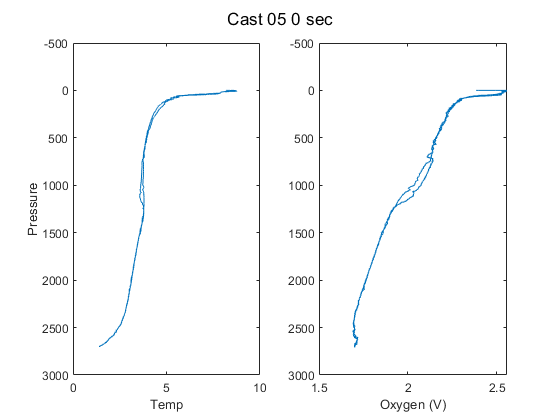

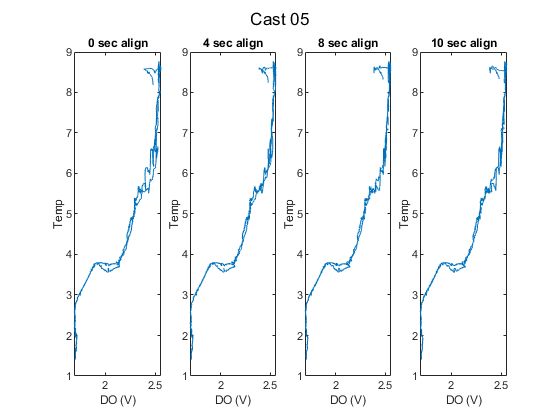

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

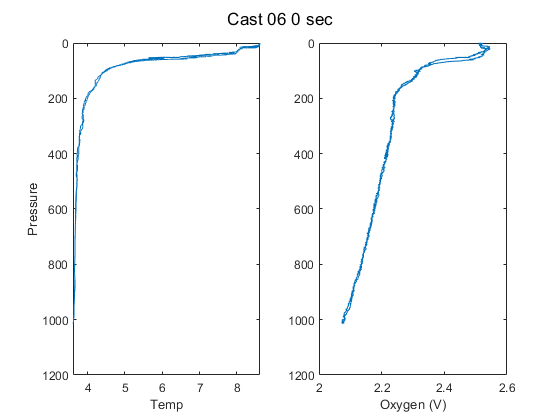

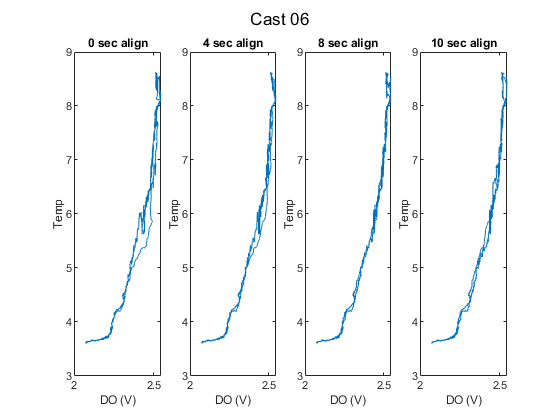

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

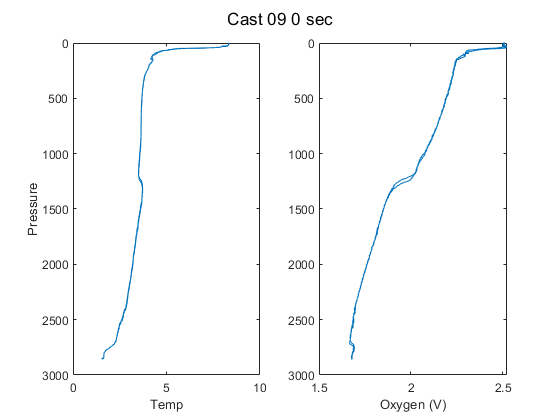

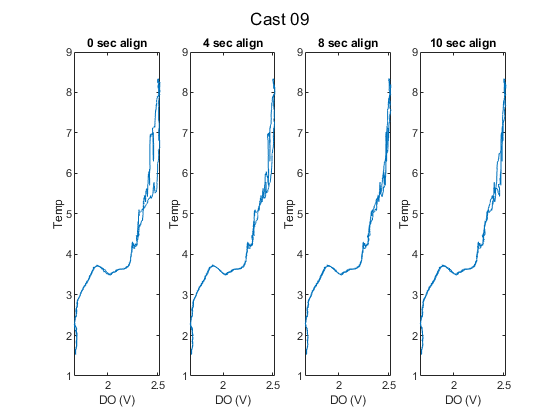

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

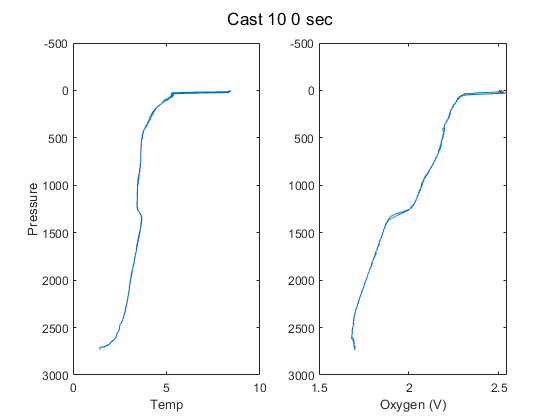

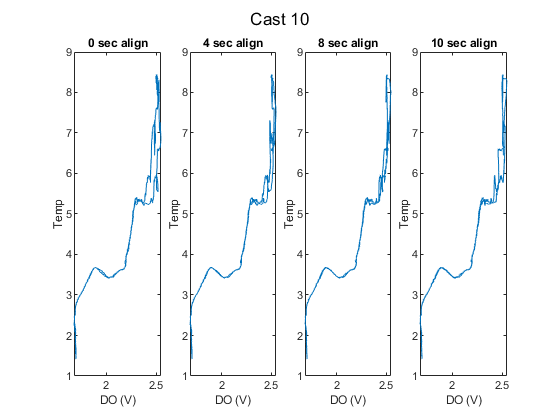

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);

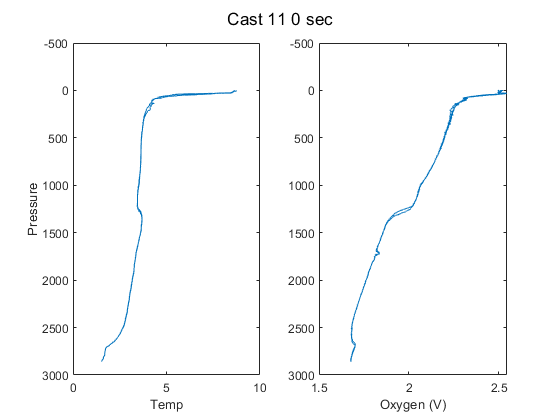

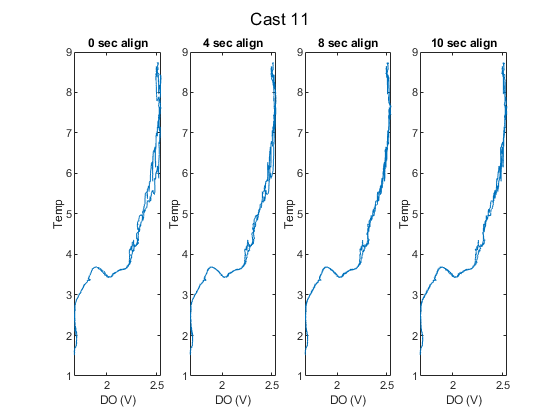

cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);

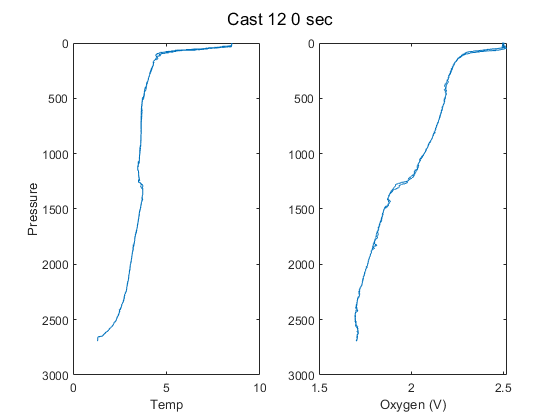

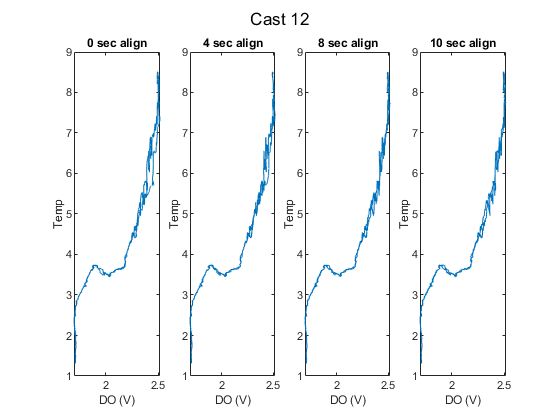

cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);

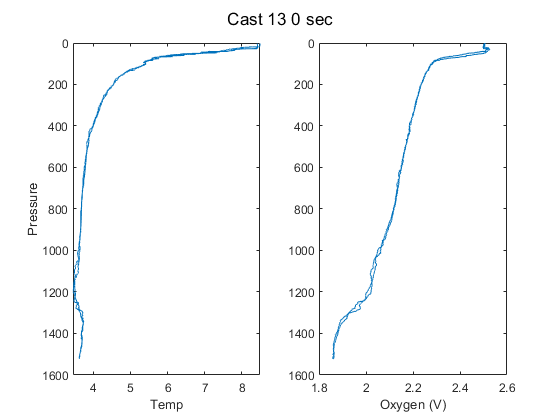

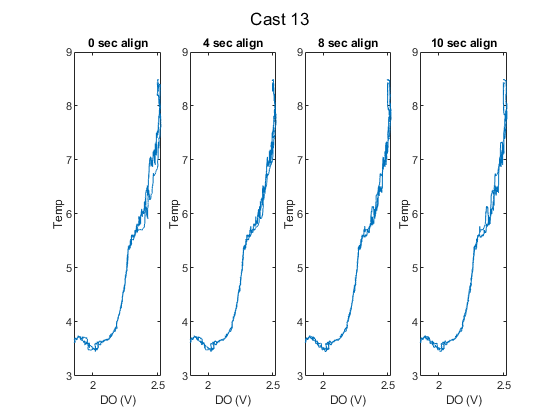

cast13 = align_CTD_KF(cast13,'Cast 13',a1,a2,a3);


% Pick align_sec

% % If playing with hysteresis coefficients you need to align sensor first 
align_sec = a2; 
% cast03.DOv = SBE_alignCTDW(cast03.sbeox0V, align_sec, 1/24 );
% cast04.DOv = SBE_alignCTDW(cast04.sbeox0V, align_sec, 1/24 );
% cast05.DOv = SBE_alignCTDW(cast05.sbeox0V, align_sec, 1/24 );
% cast06.DOv = SBE_alignCTDW(cast06.sbeox0V, align_sec, 1/24 );
% cast09.DOv = SBE_alignCTDW(cast09.sbeox0V, align_sec, 1/24 );
% cast10.DOv = SBE_alignCTDW(cast10.sbeox0V, align_sec, 1/24 );
% cast11.DOv = SBE_alignCTDW(cast11.sbeox0V, align_sec, 1/24 );
% cast12.DOv = SBE_alignCTDW(cast12.sbeox0V, align_sec, 1/24 );
% cast13.DOv = SBE_alignCTDW(cast13.sbeox0V, align_sec, 1/24 );

% H = [-0.02, 5000, 1850]; 
% align = 1; 
% [cast03] = adjust_hysteresis_KF(cast03,'Cast 03',H,cal,align);
% [cast04] = adjust_hysteresis_KF(cast04,'Cast 04',H,cal,align);
% [cast05] = adjust_hysteresis_KF(cast05,'Cast 05',H,cal,align);

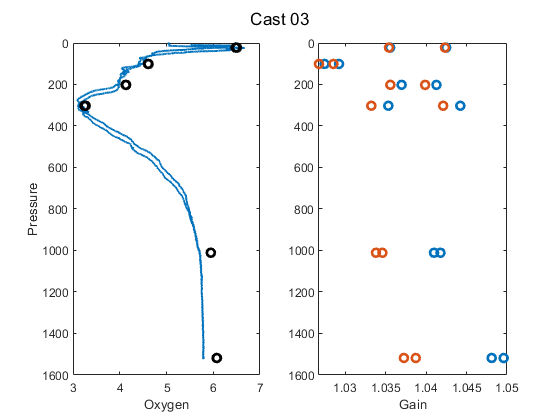

Gain = 1.0394+/- 0.0067936
EGain = 1.0359+/- 0.0048636


E = cal.E;
E2 = 3.78e-2; 

btlsum03 = CTD_Gain_KF(btlsum03,cast03,'Cast 03',E,E2);

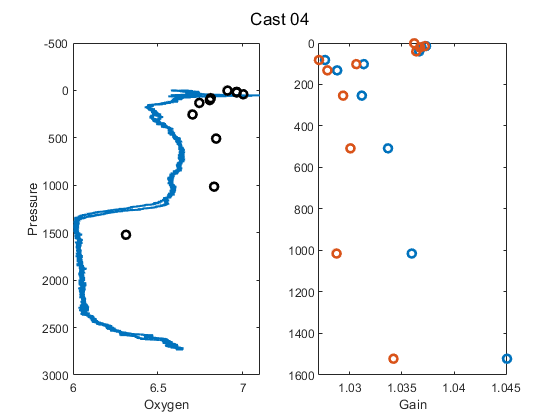

Gain = 1.0346+/- 0.004853
EGain = 1.0324+/- 0.0039062


btlsum04 = CTD_Gain_KF(btlsum04,cast04,'Cast 04',E,E2);

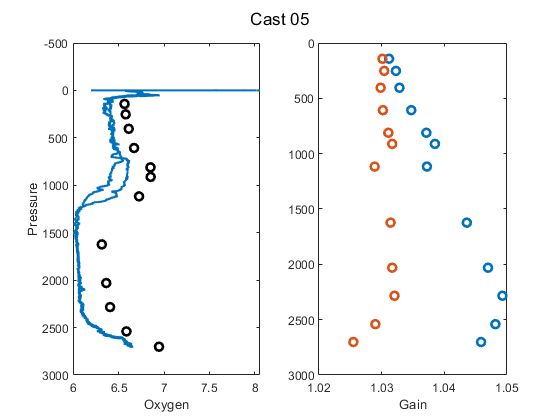

Gain = 1.0398+/- 0.0066222
EGain = 1.0311+/- 0.0017267


btlsum05 = CTD_Gain_KF(btlsum05,cast05,'Cast 05',E,E2);

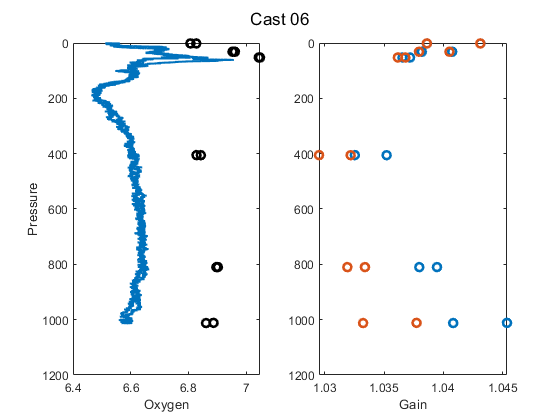

Gain = 1.0388+/- 0.003446
EGain = 1.0362+/- 0.0037989


btlsum06 = CTD_Gain_KF(btlsum06,cast06,'Cast 06',E,E2);

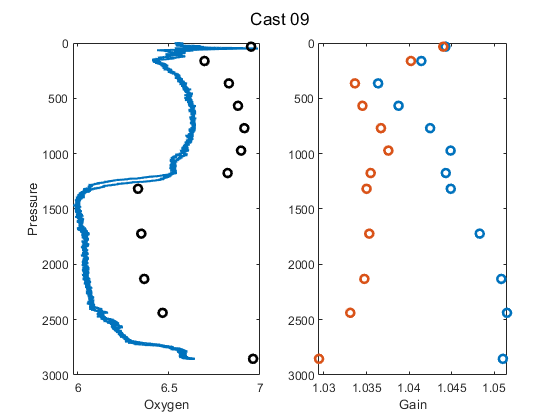

Gain = 1.0449+/- 0.0048361
EGain = 1.0367+/- 0.0031837


btlsum09 = CTD_Gain_KF(btlsum09,cast09,'Cast 09',E,E2);

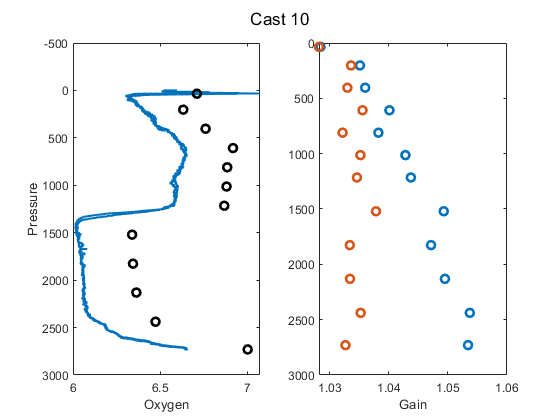

Gain = 1.0431+/- 0.0078427
EGain = 1.0347+/- 0.0026389


btlsum10 = CTD_Gain_KF(btlsum10,cast10,'Cast 10',E,E2);

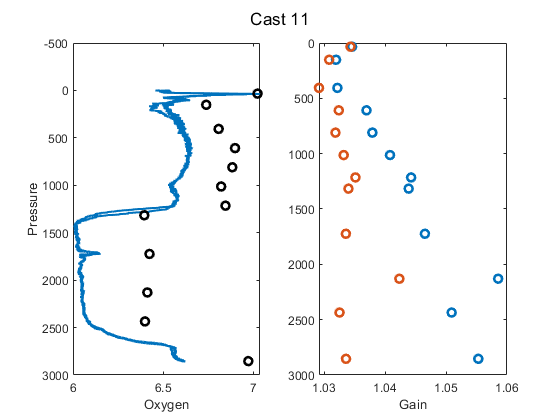

Gain = 1.0428+/- 0.0087761
EGain = 1.0345+/- 0.0035535


btlsum11 = CTD_Gain_KF(btlsum11,cast11,'Cast 11',E,E2);

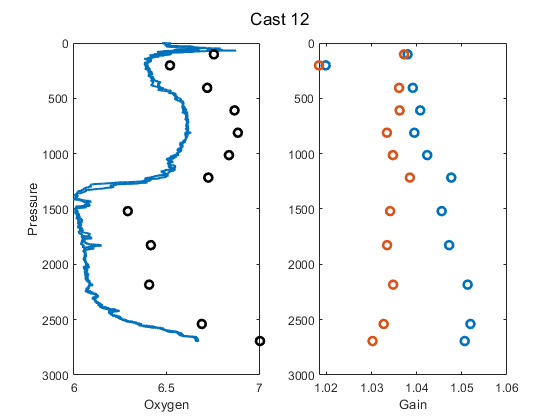

Gain = 1.0428+/- 0.0087691
EGain = 1.0343+/- 0.0052734


btlsum12 = CTD_Gain_KF(btlsum12,cast12,'Cast 12',E,E2);

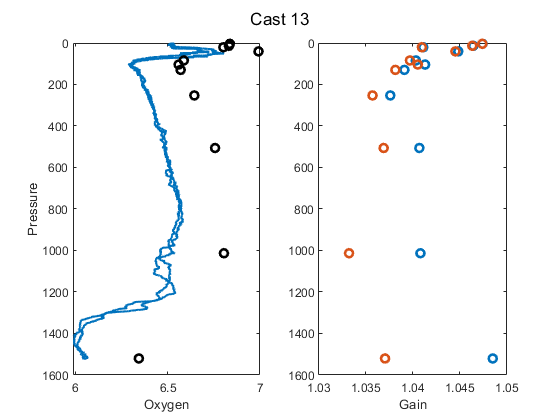

Gain = 1.0425+/- 0.0036159
EGain = 1.0403+/- 0.0042775


btlsum13 = CTD_Gain_KF(btlsum13,cast13,'Cast 13',E,E2);

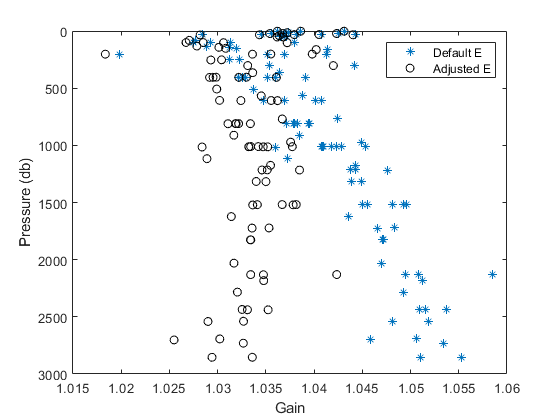


btlsum = [btlsum03; btlsum04; btlsum05; btlsum06;...
    btlsum09; btlsum10; btlsum11; btlsum12];

depth_cut = 500;

figure
plot(btlsum.gain,btlsum.PrDM,'*')
hold on
plot(btlsum.Egain,btlsum.PrDM,'ok')
% plot(btlsum.Egain(btlsum.PrDM > depth_cut),btlsum.PrDM(btlsum.PrDM > depth_cut),'ok')
axis ij
ylabel('Pressure (db)')
xlabel('Gain')
legend('Default E','Adjusted E','Location','NE')


disp(['Gain = ' num2str(nanmean(btlsum.gain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.gain(btlsum.PrDM > depth_cut)))])

Gain = 1.0448+/- 0.0056405


disp(['EGain = ' num2str(nanmean(btlsum.Egain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.Egain(btlsum.PrDM > depth_cut)))])

EGain = 1.0347+/- 0.0028198


cal.SOCnew = cal.SOC*nanmean(btlsum.Egain(btlsum.PrDM > depth_cut));
disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 8


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term = ' num2str(E2)])

Adjust. E term = 0.0378


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.51515


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.53302
